# Visualize Behavioral Performance

A key point of the study is to examine the neural processing of sound during perceptual constancy. We must therefore check whether listeners discriminate sounds equally well when vowels are generated with different fundamental frequencies (F0s), sound levels and voicing parameters, as well as when sounds are presented from different locations.

The plots generated here appear in the paper in Figure 1C and cover the four subjects for which we recorded responses of neurons during task performance:

% Subject name
ferrets = {'F1201_Florence','F1203_Virginia','F1217_Clio','F1304_Flea'};
       
% Subject name, first formant of vowels associated with left and right responses on correct trials
contingencies = {'F1201_Florence', 460, 730;        
                 'F1203_Virginia', 460, 730;
                 'F1217_Clio',     730, 460;
                 'F1304_Flea',     437, 936};      

% Color scheme
colors = [1 0.5 0;      % Florence
          1 0 0;        % Virginia
          0 0.5 1;          % Clio
          0.5 0.25 0.08];   % Flea

% Minimum number of trials for a stimulus condition to be accepted (for
% each subject)
reqTrials = 40;

% Define path to behavioral data
data_dir = 'C:\Users\steph\Documents\GitHub\perceptual_constancy_for_vowels\data\behavior';

### Fundamental Frequency: Vowels of different pitch 

We'll start by comparing vowel discrimination performance of each listener as a function of fundamental frequency. Data is shown as a line plot (lines represent different subjects) and the overall performance of each ferret is also printed to the console. Also reported is the probability of observing that performance if responses followed a binomial distribution with equal probability of correct and error responses (i.e. so we can determine if animals were performing significantly better than chance).

% Path to text files containing source data
pathname = fullfile(data_dir, 'pitch');

% Define headers for files generated by GoFerret
headers = {'Trial','CorrectionTrial','StartTime','CenterReward',...
            'F1','F2','F3','F4','HoldTime','Atten','Pitch','Side',...
            'Response','RespTime','Correct'};
      
% Set up figures
figure
axes('nextPlot','add')

xlabel('F0 (Hz)')
ylabel('% Correct')
ylim([0 100])
title('Pitch Constancy - Behavioral data')

% Set up legend names
[legStr, hp] = deal([]);

% For each ferret
for i = 1 : numel(ferrets)
    
    % List behavioral files (corrected for calibration
    ferDir = fullfile( pathname, ferrets{i});
    files  = dir( fullfile(ferDir, '*Level*.txt'));    
    T = [];
    
    % Specific continencies
    cIdx  = strcmp(contingencies(:,1), ferrets{i});
    ruleF = cell2mat(contingencies(cIdx,2:3));
    
    % Build behavioral record
    for j = 1 : numel(files)
        
        % Skip level 37 files (i.e. sessions where a single vowel token was
        % presented, rather than the two tokens in other sessions)
        if contains(files(j).name,'level37')
            continue
        end
        
        % Import data
        B = importdata( fullfile( ferDir, files(j).name));
        
        if isempty(B), continue; end
        
        % Convert to table        
        B = array2table(B.data,'VariableNames',headers);    

        % Filter for trial parameters                
        B(B.CorrectionTrial == 1,:) = [];   % Remove correction trials             
        B(B.Correct == -1,:) = [];          % Remove abort trials     
        
        % Add to all data
        T = [T; B];
    end
    
    % Run logisitic regression
    mdl = fitglm(T.Pitch, T.Correct,'distribution','binomial');
    
    % Run binomial test
    pBinom = myBinomTest(nansum(T.Correct), size(T,1), 0.5);
    fprintf('%s: %d / %d correct: binomial p = %.5f\n', ferrets{i}, nansum(T.Correct), size(T,1), pBinom)
    
    % Get spatial masks
    [nUniqueX, uniqueX, nXUnique] = nUnique(T.Pitch);
    y = nan(nUniqueX,1);
    
    for j = 1 : nUniqueX       
        y(j) = mean(T.Correct(T.Pitch == uniqueX(j)));        
    end
    
    y = y .* 100; % convert proportion to percentage
    
    % Filter for trial number
    uniqueX = uniqueX( nXUnique >= reqTrials);
    y = y( nXUnique >= reqTrials);
    
    % Plot performance vs F0
    h = plot(uniqueX, y, '-o',...
           'Color', colors(i,:),...
           'MarkerEdgeColor', colors(i,:),...
           'tag', ferrets{i},...
           'Userdata', nXUnique,...
           'LineWidth', 1);       
          
    % Remember name for legend
   hp = [hp; h];   
   legStr = [legStr; {strrep(ferrets{i},'_',' ')}];
end

F1201_Florence: 10214 / 12032 correct: binomial p = 0.00000


F1203_Virginia: 8502 / 9945 correct: binomial p = 0.00000


F1217_Clio: 3946 / 4792 correct: binomial p = 0.00000


F1304_Flea: 1051 / 1487 correct: binomial p = 0.00000


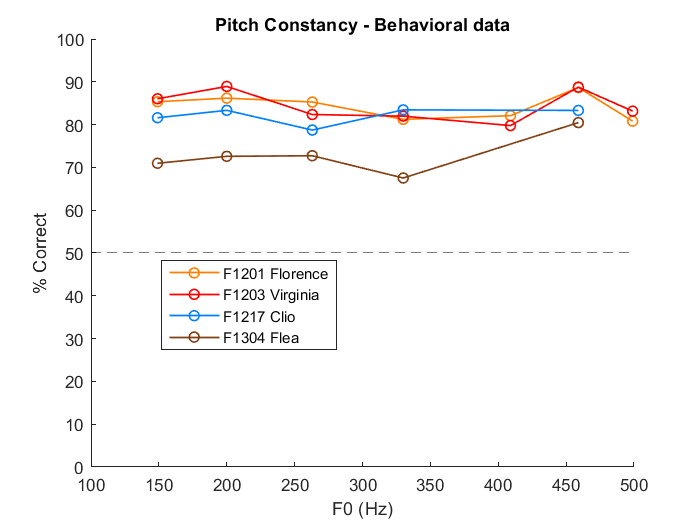


plot(xlim,[50 50],'--k')    % Chance performance line

myL = legend(hp, legStr);
set(myL,'position',[0.2298 0.3341 0.2518 0.1698])

#### Supplementary Analysis: Effect of vowel repetition

In our behavioral task, we presented listeners with two tokens of a particular vowel on each trial. The motivation for repeating the vowel was to match earlier work in which two repeats were used. However we also conducted some test sessions with only one token of the vowel to check that animals could still perform the task. Here, we plot the performance of the three subjects that were tested in both conditions:

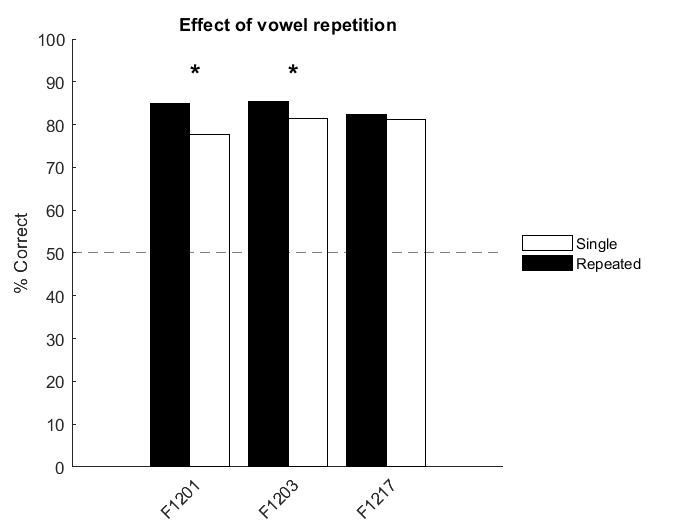

% Set up figure
figure
hold on

ylabel('% Correct')
title('Effect of vowel repetition')

xIdx = 0;   % Counter for bar centers
xStr = []; % Containter for xtick labels

% For each ferret
for i = 1 : numel(ferrets)
    
    % List behavioral files 
    ferDir = fullfile( pathname, ferrets{i});
    files  = dir( fullfile(ferDir, '*Level*.txt'));    
    T = [];
    
    % Build behavioral record
    for j = 1 : numel(files)
        
        % Note level 37 files
        vowelRep = true;
        if contains(files(j).name,'level37'), vowelRep = false; end
        
        % Import data
        B = importdata( fullfile( ferDir, files(j).name));
        
        if isempty(B), continue; end
        
        % Convert to table        
        B = array2table(B.data,'VariableNames',headers);    

        % Filter for trial parameters                
        B(B.CorrectionTrial == 1,:) = [];   % Remove correction trials             
        B(B.Correct == -1,:) = [];          % Remove abort trials     
        
        % Check for weird stimuli
        if any(B.F1 == 595), error('weird stimuli'), end
        
        % Note condition
        B.VowelRepeated = repmat(vowelRep, size(B,1), 1);
        
        % Add to all data
        T = [T; B];
    end
    
    % Skip animals we didn't test single stimulus
    if all(T.VowelRepeated), continue; end    
    xIdx = xIdx + 1;
    xStr{xIdx} = ferrets{i}(1:5);    
    
    % Plot performance
    singlePerformance   = nanmean(T.Correct(~T.VowelRepeated)) * 100;
    repeatedPerformance = nanmean(T.Correct(T.VowelRepeated == 1)) * 100;
    
    b(1) = bar(i+0.2, singlePerformance,'w','BarWidth',0.4);
    b(2) = bar(i-0.2, repeatedPerformance,'k','BarWidth',0.4);
        
    % Compare performance statistically
    mdl = fitglm(T.Correct, T.VowelRepeated,'distribution','binomial');
    p   =  mdl.Coefficients.pValue(2);
    
    if p < 0.05
       text(xIdx, 92, '*','FontSize',16,'FontWeight','Bold','UserData',p) 
    end
end

plot(xlim,[50 50],'--k')    % Chance performance line

set(gca,'xtick',1:xIdx,'xticklabel',xStr,'XTickLabelRotation',45,'ylim',[0 100])
lh = legend(b,'Single','Repeated');
set(lh,'EdgeColor','none','Location','eastoutside')

From this plot, we can see that reducing the number of vowel tokens on each trial from two to oen does have a significant impact on the performance of two animals, but even in those cases, performance was well above chance levels (50%).

### Spatial invariance

Sounds were presented from a single speaker, either to the left or right of the head. This dataset forms part of a broader study into spatial release from energetic masking in which vowels were presented from one speaker, and noise was presented at either the same location or the alternative speaker ([Town et al. 2023)](https://www.jneurosci.org/content/43/5/749.abstract).


% Path to file containing original text files generated during testing
pathname = fullfile(data_dir, 'space');

% Define headers (these are different from those generated during pitch
% testing)
headers = {'Trial','CorrectionTrial','StartTime','CenterReward',...
            'F1','F2','F3','F4','HoldTime','Atten','Pitch','Side',...
            'Response','RespTime','Correct','SpatialMask'};
                
% Set up figure
figure();
ax1 = axes('nextPlot','add','xtick',[4 5],'xticklabel',{'Left','Right'});

xlabel('Location')
ylabel('% Correct')
xlim([3.5 5.5])
ylim([0 100])
title('Space')

% Set up legend names
[legStr, hp] = deal([]);

% For the three ferrets that were tested with vowels at different locations
for i = 1 : 3
    
    % List behavioral files
    ferDir = fullfile( pathname, ferrets{i});
    files = dir( fullfile(ferDir, '*.txt'));
    T = table;
    
    % Specific continencies
    cIdx  = strcmp(contingencies(:,1), ferrets{i});
    ruleF = cell2mat(contingencies(cIdx,2:3));
    
    % Build behavioral record
    for j = 1 : numel(files)
        
        % Import data
        B = importdata( fullfile( ferDir, files(j).name));
        B = array2table(B.data,'VariableNames',headers);        

        % Filter for trial parameters                
        B(B.CorrectionTrial == 1,:) = [];   % Remove correction trials                           
        B(B.Correct == -1,:) = [];          % Remove abort trials     
        B(B.SpatialMask < 4,:) = [];        % Filter for Signal only conditions
        
        % Append to table
        B.Session_index = repmat(j, size(B,1), 1);
        T = [T; B];
    end
    
    % Run binomial test
    pBinom = myBinomTest(sum(T.Correct), size(T,1), 0.5);
    fprintf('%s: %d / %d correct: binomial p = %.5f\n', ferrets{i}, sum(T.Correct), size(T,1), pBinom)
 
    % Get spatial masks
    [nUniqueX, uniqueX, nXUnique] = nUnique(T.SpatialMask);
    y = nan(nUniqueX,1);
    
    for j = 1 : nUniqueX       
        y(j) = mean(T.Correct(T.SpatialMask == uniqueX(j)));        
    end
    
    y = y .* 100; % convert proportion to percentage
        
    % Plot performance vs Location
    h = plot(uniqueX, y, '-o',...
           'Color', colors(i,:),...
           'MarkerEdgeColor',   colors(i,:),...
           'tag',               ferrets{i},...
           'Userdata',          nXUnique,...
           'LineWidth',         1,...
           'Parent',            ax1);      

   % Remember name
   hp = [hp; h];
   legStr = [legStr; {strrep(ferrets{i},'_',' ')}];
end

F1201_Florence: 776 / 957 correct: binomial p = 0.00000


F1203_Virginia: 641 / 789 correct: binomial p = 0.00000


F1217_Clio: 577 / 717 correct: binomial p = 0.00000


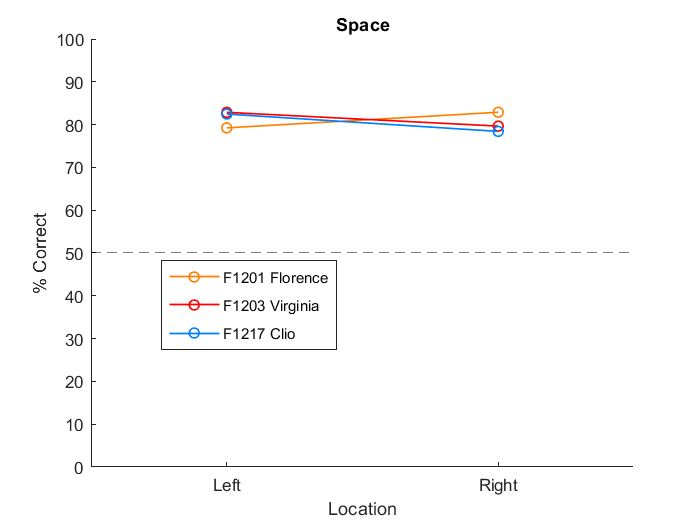


% Plot chance performance
plot(xlim,[50 50],'--k')

myL = legend(hp, legStr);
set(myL,'position',[0.2298 0.3341 0.2518 0.1698])

### Level invariance

Although we know that our ability to recognize sounds does depend on sound level (because we have thresholds below which sounds cannot be detected), we also have the ability to recognize and discriminate between sounds across a wide range of sound pressure levels. This section examines whether the same is true for ferrets in the current study.

reqTrials = 10;

pathname = fullfile(data_dir, 'level');

% Set up figure
figure();
ax1 = axes('nextPlot','add');
xlabel('Level (dB SPL)')
ylabel('% Correct')
ylim([0 100])
title('Sound level')

% Set up legend names
[legStr, hp] = deal([]);

% For each ferret
for i = 1 : numel(ferrets)
    
    % List behavioral files (corrected for calibration
    ferDir = fullfile( pathname, ferrets{i});
    files  = dir( fullfile(ferDir, '*.mat'));
    T = [];
    
    % Build behavioral record
    for j = 1 : numel(files)
        
        % Import data
        B = importdata( fullfile( ferDir, files(j).name));
        
        if isempty(B), continue; end
        
        % Filter for trial parameters
        B(B.CorrectionTrial == 1,:) = [];   % Remove correction trials
        B(B.Correct == -1,:) = [];          % Remove abort trials
        
        % Add to all data
        T = [T; B];
    end
    
    % Get levels
    [nUniqueX, uniqueX, nXUnique] = nUnique(T.Level_SPL);
    y = nan(nUniqueX,1);
    
    % For each level
    for j = 1 : nUniqueX
        
        % Filter data
        currentLevel = uniqueX(j);
        S = T(T.Level_SPL == currentLevel,:);
        
        % Report performance
        y(j) = mean(S.Correct);
        
        % Run binomial test
        if size(S,1) >= reqTrials   
            pBinom = myBinomTest(sum(S.Correct), size(S,1), 0.5);
            fprintf('%s: %.1f dB SPL: %d / %d: p = %.5f\n',...
                ferrets{i}, currentLevel, sum(S.Correct), size(S,1), pBinom)
        end
    end
    
    y = y .* 100; % convert proportion to percentage
    
    % Filter for trial number
    uniqueX = uniqueX( nXUnique >= reqTrials);
    y = y( nXUnique >= reqTrials);
   
    % Plot data
    h = plot(uniqueX, y, '-o',...
        'Color',             colors(i,:),...
        'MarkerEdgeColor',   colors(i,:),...
        'tag',               ferrets{i},...
        'Userdata',          nXUnique,...
        'LineWidth',         1,...
        'Parent',            ax1);
       
    
    % Remember name
    hp = [hp; h];
    legStr = [legStr; {strrep(ferrets{i},'_',' ')}];
end

F1201_Florence: 45.0 dB SPL: 138 / 186: p = 0.00000
F1201_Florence: 52.5 dB SPL: 151 / 193: p = 0.00000
F1201_Florence: 60.0 dB SPL: 161 / 192: p = 0.00000
F1201_Florence: 64.5 dB SPL: 438 / 498: p = 0.00000
F1201_Florence: 67.5 dB SPL: 175 / 195: p = 0.00000
F1201_Florence: 69.0 dB SPL: 479 / 523: p = 0.00000
F1201_Florence: 73.5 dB SPL: 460 / 515: p = 0.00000
F1201_Florence: 75.0 dB SPL: 168 / 187: p = 0.00000
F1201_Florence: 78.0 dB SPL: 445 / 501: p = 0.00000
F1201_Florence: 82.5 dB SPL: 445 / 500: p = 0.00000


F1203_Virginia: 45.0 dB SPL: 149 / 196: p = 0.00000
F1203_Virginia: 52.5 dB SPL: 169 / 205: p = 0.00000
F1203_Virginia: 60.0 dB SPL: 162 / 188: p = 0.00000
F1203_Virginia: 64.5 dB SPL: 372 / 414: p = 0.00000
F1203_Virginia: 67.5 dB SPL: 176 / 198: p = 0.00000
F1203_Virginia: 69.0 dB SPL: 357 / 397: p = 0.00000
F1203_Virginia: 73.5 dB SPL: 352 / 407: p = 0.00000
F1203_Virginia: 75.0 dB SPL: 179 / 197: p = 0.00000
F1203_Virginia: 78.0 dB SPL: 382 / 434: p = 0.00000
F1203_Virginia: 82.5 dB SPL: 357 / 424: p = 0.00000


F1217_Clio: 64.5 dB SPL: 341 / 442: p = 0.00000
F1217_Clio: 69.0 dB SPL: 345 / 449: p = 0.00000
F1217_Clio: 73.5 dB SPL: 380 / 457: p = 0.00000
F1217_Clio: 78.0 dB SPL: 392 / 442: p = 0.00000
F1217_Clio: 82.5 dB SPL: 366 / 424: p = 0.00000


F1304_Flea: 61.5 dB SPL: 65 / 98: p = 0.00160
F1304_Flea: 66.0 dB SPL: 62 / 85: p = 0.00003
F1304_Flea: 70.5 dB SPL: 69 / 101: p = 0.00030
F1304_Flea: 75.0 dB SPL: 49 / 80: p = 0.05666
F1304_Flea: 79.5 dB SPL: 64 / 91: p = 0.00013


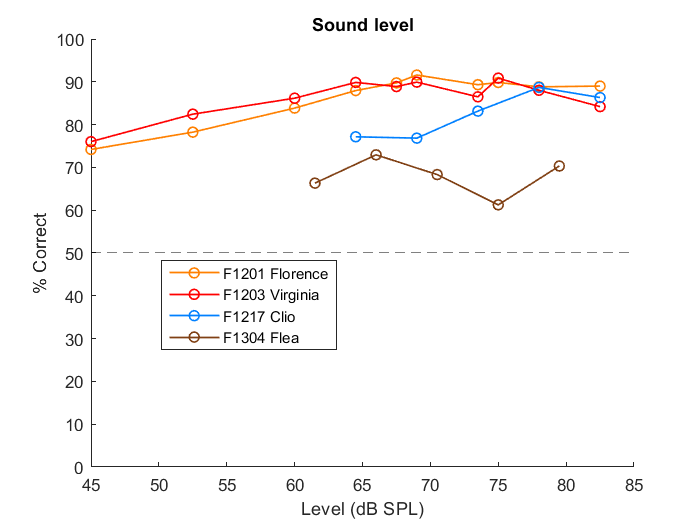


% Add horizontal line for chance performance
plot(xlim,[50 50],'--k')

% Show legend
myL = legend(hp, legStr);
set(myL,'position',[0.2298 0.3341 0.2518 0.1698])